   __           _             
  / _|         (_)            
 | |_ _   _ ___ _  ___  _ __   
 |  _| | | / __| |/ _ \| `_ \    :- Functional and Structural 
 | | | |_| \__ \ | (_) | | | |      Integration of Neuroimages
 |_|  \__,_|___/_|\___/|_| |_|

 Generating ROIs in present working directory:
	C:\Users\yhare\OneDrive\Documents\MATLAB\fusion-watershed

 Loading image:
	C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\HIT\sub-04_simplemodel_HIT.nii

 Input kind:
	 thresholded: false
	 two-tailed: true

 Unthresholded map: 
	 Applying threshold to positive & negative values...	

 Segmenting positives	***** Completed in 0.55228 seconds

 Segmenting negatives	 Completed in 0.020029 seconds

 Combining labels
 Interpolating atlases          ******** Completed in 0.59451 seconds

 Assigning labels to 9 ROIs	*********
                                Completed in 0.281 seconds

 Generating interactive figure


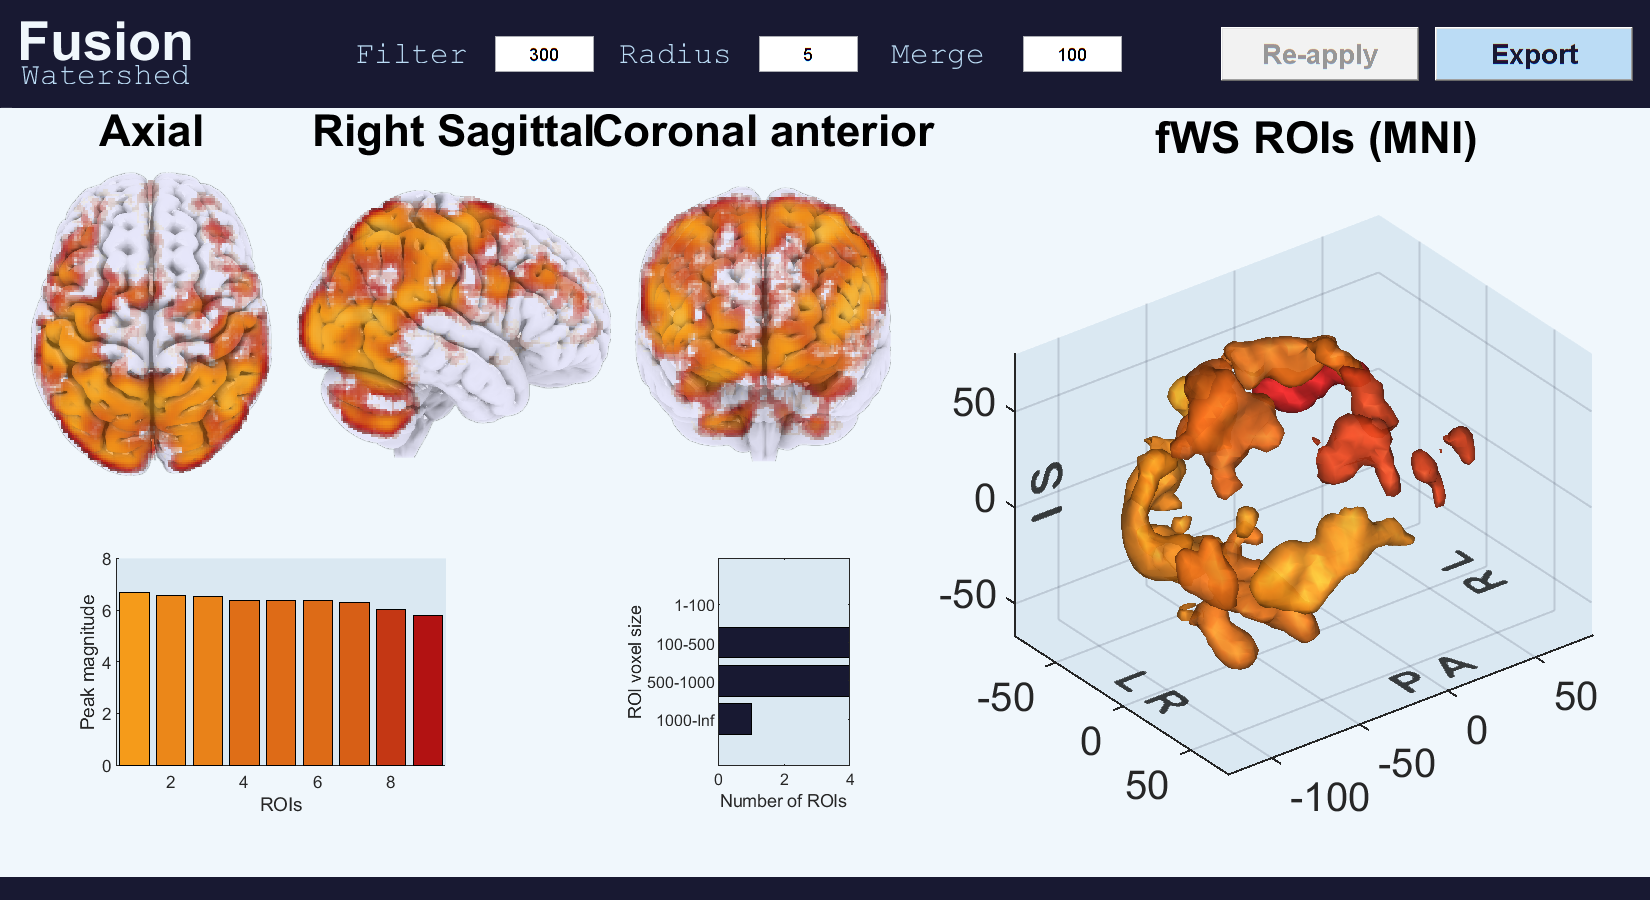

 Completed segmentation & ROI visualisation in 42.0641 seconds


datapath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\';
addpath(genpath(datapath));

level = 'subject-level';
condition = 'HealthLoss';
subject = 'sub-04';

filepath = fullfile(datapath, level, condition, strcat(subject, '_simplemodel_', condition, '.nii'));
obj = fws.generate_ROI(filepath,'threshold_method','z','threshold_value', 0.015,'merge', 100, 'radius', 5);

fwspath = spm_file(filepath,'ext','','suffix','_fws')

fwspath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\HIT\sub-04_simplemodel_HIT_fws'

csvpath = spm_file(fwspath,'ext','csv')

csvpath = 'C:\Users\yhare\GitHub\shinobi_fmri\data\thresholded_z_maps\subject-level\HIT\sub-04_simplemodel_HIT_fws.csv'

save.vol(obj.label, obj.grid, fwspath,'Compressed',false);
writetable(obj.table, csvpath);